% Description: 
%This script is used to generate specific genome-scale models from a stratified set of 90 samples from the TCGA-BRCA 
% breast cancer dataset, a small manual curation of bibliomic information, and a generic genome-scale model, 
% in this case Recon3D

% Initialize CobraToolbox

initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2025
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.39.5).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver('glpk', 'all');


 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > changeCobraSolver: Solver for LP problems has been set to mosek.

 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > changeCobraSolver: Solver for QP problems has been set to mosek.

 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > changeCobraSolver: Solver for EP problems has been set to mosek.

 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > changeCobraSolver: Solver for CLP problems has been set to mosek.
 > changeCobraSolver: Solver mosek not supported for problems of type MILP. Currently used: glpk 
 > changeCobraSolver: Solver mosek not supported for problems of type MIQP. No solver set for this problemtype 
 > changeCobraSolver: Solver mosek not supported for problems of type NLP. Currently used: matlab 



% Define generic model path

model = readCbModel('/Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/Recon3D_301.mat');

Each model.subSystems{x} has been changed to a character array.


% Quita el punto y lo que sigue
for i = 1:numel(model.genes)
    % Divide por el punto y toma la primera parte
    parts = split(model.genes{i}, '.');
    model.genes{i} = parts{1};
end

% Define xomics data path
% Load Xomics Files
XomicsFilesPath = '/Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/GEMs cancer';

% Get Xomics files info
XomicsFilesInfo = dir(fullfile(XomicsFilesPath, '*.txt'));

% Get Xomics files names (full paths)
XomicsFilesNames = {};
for i = 1:length(XomicsFilesInfo)
    XomicsFileName = XomicsFilesInfo(i).name;
    fullPath = fullfile(XomicsFilesPath, XomicsFileName);
    XomicsFilesNames{i,1} = fullPath;

    % Read table
    T = readtable(fullPath);
end

% Get file names without extension .txt
filesNames = {};
for i = 1:length(XomicsFilesInfo)
    [~, XomicsFileName, ~] = fileparts(XomicsFilesInfo(i).name);
    filesNames{i,1} = XomicsFileName;
end


%% Load Bibliomic data

% Define bibliomic data path
bibliomicDataPath = '/Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/Bibliomic_Gems_actualizado2.xlsx';

% Load bibliomic data and process it
specificData = preprocessingOmicsModel(bibliomicDataPath);

Reading inputData from : /Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/Bibliomic_Gems_actualizado2.xlsx
Reading sheet: activeGenes
Reading sheet: essentialAA
Reading sheet: rxns2constrain
Reading sheet: activeReactions
Reading sheet: presentMetabolites
Reading sheet: rxns2add


--------------------------------------------------------------
 
XomicsToModel input specificData:
 
             inputData: '/Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/Bibliomic_Gems_actualizado2.xlsx'
           activeGenes: {108×1 cell}
           essentialAA: [9×1 table]
        rxns2constrain: [7×5 table]
       activeReactions: {1459×1 cell}
    presentMetabolites: [39×3 table]
              rxns2add: [2×8 table]
    transcriptomicData: [23053×2 table]
           rxns2remove: []
         inactiveGenes: []

XomicsToModel input param:
 
        inactiveGenesTranscriptomics: 1
                   curationOverOmics: 0
                  metabolomicWeights: 'mean'
             transcriptomicThreshold: 0.05
                    weightsFromOmics: 1
                        fluxCCmethod: 'fastcc'
                          printLevel: 3
                               debug: 0
                       diaryFilename: 0
                  allowRxnRelaxation: 1
   

 
Feasible generic input model.
 
--------------------------------------------------------------
 
Generating model without an objective function.
 
 
--------------------------------------------------------------
Adding 2 reactions ...
 
Metabolite M_cancer_biomass[c] not in model - added to the model


biomass_ob	0.00537 35cgmp[c] + 0.59421 glu_L[c] + 2.4523 asp_L[c] + 0.01963 amp[c] + 0.00805 damp[c] + 0.03272 cmp[c] + 0.02452 pa_hs[c] + 0.42021 ala_L[c] + 0.04268 asn_L[c] + 0.00427 cys_L[c] + 0.67628 gln_L[c] + 0.49244 gly[c] + 0.13132 ser_L[c] + 0.07222 thr_L[c] + 0.03283 lys_L[c] + 0.00328 arg_L[c] + 0.00657 met_L[c] + 0.00646 pail_hs[c] + 0.00347 dag_hs[c] + 0.03755 chsterol[c] + 0.00077 clpn_hs[c] + 0.00537 dcmp[c] + 0.03709 gmp[c] + 0.01963 ump[c] + 0.10177 his_L[c] + 0.0197 tyr_L[c] + 0.01313 ile_L[c] + 0.0394 leu_L[c] + 0.00354 lpchol_hs[c] + 0.00489 mag_hs[c] + 0.00328 trp_L[c] + 0.01313 phe_L[c] + 0.06369 pro_L[c] + 0.01087 ps_hs[c] + 0.00706 sphmyln_hs[c] + 0.04268 val_L[c] + 0.01925 xolest2_hs[c] + 0.00805 dtmp[c] + 0.03407 HC02080[c] + 0.93989 M03161[c] 	->	M_cancer_biomass[c] 
biomass_ex	M_cancer_biomass[c] 	->	
Found biomass reaction: biomass_ob
ATP maintenance reaction is not considered an exchange reaction by default. It should be mass balanced:
ATPM	h2o[c] + atp[c]

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


6.99484e-07 = ||N'*z|| (should be zero)
1171/11646 reactions relaxed.
  8381	 10475	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8381	 10475	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8381	 10475	Confirmed stoichiometrically consistent by leak/siphon testing.
    15	  1171	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 147 metabolites.
arachidonates	12RHPET[c] + prostg1[c] + 12harachd[r] + wharachd[r] + 18harachd[r] + prostge2[r] + 13_cis_retnglc[r] + wharachd[c] + CE0737[c] + CE1243[c] + CE5531[r] + CE4993[c] + CE4993[m] + CE4993[x] + CE2568[c] + CE2568[r] + CE2568[x] + CE2569[c] + CE2569[r] + CE2569[x] + CE5700[c] + CE5726[c] + CE5727[c] + CE5730[c] + C05957[r] + CE4936[c] + CE4936[n] + C05284[c] + C05284[m] + C05284[r] + CE0955[r] + CE3554[c] + CE5141[c] + C06315[r] + C06315[x] + C06314[r] + C06314[x] + CE2305[c] + CE2305[r] + CE2306[c] + CE2306[r] +

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.01581e-07 = ||N'*z|| (should be zero)
575/11645 reactions relaxed.
  8392	 11070	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8392	 11070	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8392	 11070	Confirmed stoichiometrically consistent by leak/siphon testing.
     4	   575	 ... of which are of unknown consistency.
     0	    16	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0012	M01819[e] 	->	0.0001 adrn[e] + 0.0082 arachd[e] + 0.0001 arach[e] + 0.0001 clpnd[e] + 0.0041 crvnc[e] + 0.0001 dcsptn1[e] + 0.002 dlnlcg[e] + 0.0001 eicostet[e] + 0.0001 elaid[e] + 0.3015 hdca[e] + 0.0522 hdcea[e] + 0.0001 hexc[e] + 0.0001 hpdca[e] + 0.0001 lgnc[e] + 0.0001 lneldc[e] + 0.1535 lnlc[e] + 0.0092 lnlnca[e] + 0.0001 lnlncg[e] + 0.0001 nrvnc[e] + 0.046 ocdca[e] + 0.3837 ocdcea[e] + 0.0001 ptdca[e] + 0.0001 strdnc[e] + 0.0001 tethex3[e] + 0.0001 tetpent3[e] + 0.0001 tetpent6[e] + 0.0001 tettet6[e] + 0.00

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.05465e-07 = ||N'*z|| (should be zero)
1205/11629 reactions relaxed.
  8384	 10424	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 10424	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 10424	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	  1205	 ... of which are of unknown consistency.
     0	     6	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0549	0.0007 adrncoa[c] + 0.0005 arachcoa[c] + 0.2125 arachdcoa[c] + 0.1243 pmtcoa[c] + 0.0005 hdcoa[c] + 0.0319 tdcoa[c] + 0.0166 lnlncacoa[c] + 0.0011 lnlncgcoa[c] + 0.0025 strdnccoa[c] + 0.0411 dlnlcgcoa[c] + 0.0221 tmndnccoa[c] + 0.1312 lnlccoa[c] + 0.0067 clpndcoa[c] + 0.0052 dcsptn1coa[c] + 0.0459 c226coa[c] + 0.1983 stcoa[c] + 0.0619 odecoa[c] + 0.0005 lneldccoa[c] + 0.0005 nrvnccoa[c] + 0.0005 ttccoa[c] + 0.0005 hexccoa[c] + 0.0163 eicostetcoa[c] + 0.0005 tetpent6coa[c] + 0.0005 tetpent3coa[c] + 0.0005 tettet6co

OPTIMAL


OPTIMAL


6.11517e-08 = ||N'*z|| (should be zero)
1152/11623 reactions relaxed.
  8383	 10471	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8383	 10471	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8383	 10471	Confirmed stoichiometrically consistent by leak/siphon testing.
    13	  1152	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 55 metabolites.
others	34dhoxmand[c] + 5moxact[c] + 5g2oxpt[x] + 5a2opntn[x] + im4ac[m] + mi3456p[c] + 4aabutn[c] + pepslys[r] + 6pthp[n] + selhcys[c] + dtdprmn[c] + udpxyl[g] + HC02223[m] + CE1943[c] + CE1943[e] + CE1943[x] + CE1936[c] + CE1936[x] + CE2877[c] + CE2877[r] + CE2878[c] + CE2878[r] + CE4788[c] + CE4788[x] + CE2345[m] + tdechola[c] + tdechola[x] + CE5629[c] + CE5274[c] + CE2122[c] + CE5860[c] + CE4881[c] + CE5545[c] + CE5643[c] + CE1562[c] + CE6317[c] + C08261[c] + CE5828[c] + CE5931[c] + CE5924[c] + CE7218[c] + C05708[c] + i

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.60821e-07 = ||N'*z|| (should be zero)
591/11622 reactions relaxed.
  8385	 11031	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11031	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11031	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   591	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0551	0.0031 adrncoa[c] + 0.0005 arachcoa[c] + 0.2118 arachdcoa[c] + 0.0678 pmtcoa[c] + 0.0005 hdcoa[c] + 0.0056 tdcoa[c] + 0.0019 lnlncacoa[c] + 0.0012 lnlncgcoa[c] + 0.0027 strdnccoa[c] + 0.0228 dlnlcgcoa[c] + 0.0043 tmndnccoa[c] + 0.0678 lnlccoa[c] + 0.0101 clpndcoa[c] + 0.0124 dcsptn1coa[c] + 0.0269 c226coa[c] + 0.3553 stcoa[c] + 0.136 odecoa[c] + 0.0005 lneldccoa[c] + 0.0005 nrvnccoa[c] + 0.0005 ttccoa[c] + 0.0005 hexccoa[c] + 0.0179 eicostetcoa[c] + 0.0005 tetpent6coa[c] + 0.0005 tetpent3coa[c] + 0.0005 tettet6coa

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


7.87161e-08 = ||N'*z|| (should be zero)
601/11621 reactions relaxed.
  8385	 11020	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11020	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11020	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   601	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 51 metabolites.
steroids	48dhoxquin[c] + 46dhoxquin[c] + whtststerone[r] + CE2874[r] + CE2183[c] + CE2186[c] + CE2189[c] + C05299[c] + C05299[r] + CE2184[c] + CE5239[c] + CE5239[m] + CE5239[r] + CE5239[x] + CE5242[c] + CE5242[m] + CE5242[r] + CE5242[x] + CE5243[c] + CE5243[m] + CE5243[r] + CE5243[x] + CE5244[c] + CE5244[m] + CE5244[r] + CE5244[x] + CE2176[c] + CE2174[c] + CE5072[c] + CE1293[c] + C05300[c] + C05300[r] + CE5241[c] + CE5241[m] + CE5241[r] + CE5241[x] + CE5240[c] + CE5240[m] + CE5240[r] + CE5240[x] + C05302[c] + CE3086[c] + C

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.07268e-07 = ||N'*z|| (should be zero)
579/11620 reactions relaxed.
  8385	 11041	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11041	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11041	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   579	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 43 metabolites.
xenobiotics	M00944[c] + M01175[c] + M01376[c] + M01242[c] + M00031[c] + M00246[c] + M00244[c] + M00251[c] + M00033[c] + M01302[c] + M01301[c] + M01297[c] + M01299[c] + M01156[c] + M02850[c] + M02144[c] + M01691[c] + M03042[c] + M00724[c] + M00972[c] + M00637[c] + M00571[c] + M00030[c] + M01195[c] + M03038[c] + M00927[c] + M00928[c] + M02607[c] + M00930[c] + M02589[c] + M00917[c] + M02608[c] + M01929[c] + M00542[c] + M00541[c] + M00540[c] + M00544[c] + M00543[c] + M00539[c] + M02853[c] + M00567[c] + 2 M02143[c] + M02855[c] 

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.53557e-05 = ||N'*z|| (should be zero)
631/11618 reactions relaxed.
  8383	 10987	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8383	 10987	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8383	 10987	Confirmed stoichiometrically consistent by leak/siphon testing.
    13	   631	 ... of which are of unknown consistency.
     0	     4	 removed heuristically internal reactions of unknown consistency, each involving 25 metabolites.
r1333	304 h2o[c] + 304 atp[c] + HC00001[c] 	->	304 adp[c] + 304 pi[c] + 62 glu_L[c] + 36 asp_L[c] + 63 ala_L[c] + 17 asn_L[c] + 35 cys_L[c] + 20 gln_L[c] + 13 gly[c] + 28 ser_L[c] + 29 thr_L[c] + 60 lys_L[c] + 27 arg_L[c] + 7 met_L[c] + 16 his_L[c] + 19 tyr_L[c] + 9 ile_L[c] + 64 leu_L[c] + 2 trp_L[c] + 35 phe_L[c] + 24 pro_L[c] + 43 val_L[c] 
r1335	211 h2o[c] + 211 atp[c] + HC00002[c] 	->	211 adp[c] + 211 pi[c] + 29 glu_L[c] + 25 asp_L[c] + 34 ala_L[c] + 19 asn_L[c] + 3 cys_L[c] + 17 gln_L[c] + 16 gly[c] + 30 ser_L[c] + 2

1.70727e-08 = ||N'*z|| (should be zero)
616/11614 reactions relaxed.
  8384	 10998	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 10998	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 10998	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	   616	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 24 metabolites.
HMR_9817	52 h2o[c] + 52 atp[c] + trdrd[c] 	->	52 adp[c] + 52 pi[c] + 10 glu_L[c] + 7 asp_L[c] + 8 ala_L[c] + 3 asn_L[c] + 5 cys_L[c] + 5 gln_L[c] + 5 gly[c] + 7 ser_L[c] + 4 thr_L[c] + 12 lys_L[c] + 3 met_L[c] + his_L[c] + tyr_L[c] + 4 ile_L[c] + 6 leu_L[c] + trp_L[c] + 9 phe_L[c] + 3 pro_L[c] + 11 val_L[c] 
     0	     1	 removed.
Removed reactions:
HMR_9817	HMR_9817
-------
Iteration #10 minimum cardinality of conservation relaxation vector.
    12	   615	 unknown consistency.
  8396	 11613	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.667e-07 = ||N'*z|| (should be zero)
562/11613 reactions relaxed.
  8386	 11051	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8386	 11051	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8386	 11051	Confirmed stoichiometrically consistent by leak/siphon testing.
    10	   562	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0550	0.0043 adrncoa[c] + 0.0005 arachcoa[c] + 0.2005 arachdcoa[c] + 0.0337 pmtcoa[c] + 0.0005 hdcoa[c] + 0.0055 tdcoa[c] + 0.0035 lnlncacoa[c] + 0.0011 lnlncgcoa[c] + 0.0025 strdnccoa[c] + 0.0089 dlnlcgcoa[c] + 0.0286 tmndnccoa[c] + 0.0177 lnlccoa[c] + 0.0329 clpndcoa[c] + 0.0055 dcsptn1coa[c] + 0.0931 c226coa[c] + 0.4731 stcoa[c] + 0.0323 odecoa[c] + 0.0005 lneldccoa[c] + 0.0005 nrvnccoa[c] + 0.0005 ttccoa[c] + 0.0005 hexccoa[c] + 0.0174 eicostetcoa[c] + 0.0005 tetpent6coa[c] + 0.0005 tetpent3coa[c] + 0.0005 tettet6co

OPTIMAL


OPTIMAL


OPTIMAL


5.23384e-08 = ||N'*z|| (should be zero)
583/11612 reactions relaxed.
  8385	 11029	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11029	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11029	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   583	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 43 metabolites.
HMR_5167	420 h2o[c] + 315 atp[c] + M02421[c] + 8 M02335[c] + 3 M02341[c] + 7 M02342[c] + 5 M02351[c] + 5 M02376[c] + 10 M02377[c] + 5 M02006[c] + M02380[c] + 4 M02401[c] + 6 M02404[c] + 12 M02405[c] + 3 M02408[c] + 9 M02412[c] + 3 M02415[c] + 7 M02416[c] + 4 M02419[c] + M02420[c] + 11 M02423[c] 	->	315 adp[c] + 315 pi[c] + trdrd[c] + M03081[c] + 8 M03063[c] + 3 M03065[c] + 7 M03066[c] + 5 M03067[c] + 5 M03068[c] + 10 M03069[c] + 5 M03070[c] + M03071[c] + 4 M03072[c] + 6 M03073[c] + 12 M03074[c] + 3 M03075[c] + 9 M03076[c] 

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.95367e-07 = ||N'*z|| (should be zero)
560/11611 reactions relaxed.
  8384	 11051	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 11051	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 11051	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	   560	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0560	0.557 HC02029[c] + 0.002 HC02030[c] + 0.138 HC02031[c] + 0.061 HC02032[c] + 0.025 HC02033[c] + 0.0136 HC02036[c] + 0.002 M00484[c] + 0.002 M00502[c] + 0.011 M00493[c] + 0.002 M00471[c] + 0.002 M00463[c] + 0.002 M00454[c] + 0.002 M00498[c] + 0.0358 M00461[c] + 0.002 M00481[c] + 0.002 M00438[c] + 0.002 M00469[c] + 0.002 M00448[c] + 0.0453 M00474[c] + 0.002 M00470[c] + 0.002 M00462[c] + 0.002 M00458[c] + 0.002 M00494[c] + 0.002 M00478[c] + 0.002 M00447[c] + 0.002 M00442[c] + 0.002 M00468[c] + 0.002 M00465[c] + 0.002 

OPTIMAL


OPTIMAL


OPTIMAL


3.63552e-08 = ||N'*z|| (should be zero)
552/11610 reactions relaxed.
  8386	 11058	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8386	 11058	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8386	 11058	Confirmed stoichiometrically consistent by leak/siphon testing.
    10	   552	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 26 metabolites.
r1293	420 h2o[c] + 420 atp[c] + 10 glu_L[c] + 7 asp_L[c] + 8 ala_L[c] + 3 asn_L[c] + 5 cys_L[c] + 5 gln_L[c] + 5 gly[c] + 7 ser_L[c] + 4 thr_L[c] + 12 lys_L[c] + 3 met_L[c] + his_L[c] + tyr_L[c] + 4 ile_L[c] + 6 leu_L[c] + trp_L[c] + 9 phe_L[c] + 3 pro_L[c] + 11 val_L[c] 	->	315 adp[c] + 315 pi[c] + 105 amp[c] + 105 ppi[c] + trdrd[c] 
     0	     1	 removed.
Removed reactions:
r1293	Adf Protein Assembly
-------
Iteration #14 minimum cardinality of conservation relaxation vector.
    10	   551	 unknown consistency.
  8396	 

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


3.96995e-08 = ||N'*z|| (should be zero)
577/11609 reactions relaxed.
  8385	 11032	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11032	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11032	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   577	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 23 metabolites.
r1339	133 h2o[c] + 133 atp[c] + HC00004[c] 	->	133 adp[c] + 133 pi[c] + 30 glu_L[c] + 16 asp_L[c] + 23 ala_L[c] + 5 asn_L[c] + 19 gln_L[c] + 11 gly[c] + 16 ser_L[c] + 12 thr_L[c] + 22 lys_L[c] + 17 arg_L[c] + 4 met_L[c] + 6 his_L[c] + 7 tyr_L[c] + 41 leu_L[c] + 5 trp_L[c] + 8 phe_L[c] + 10 pro_L[c] + 15 val_L[c] 
r1344	50 h2o[c] + 50 atp[c] + HC00007[c] 	->	50 adp[c] + 50 pi[c] + 8 glu_L[c] + 4 asp_L[c] + 7 ala_L[c] + asn_L[c] + 8 gln_L[c] + 5 gly[c] + 9 ser_L[c] + 10 thr_L[c] + 6 lys_L[c] + 2 arg_L[c] + 3 met_L[c] + 5 tyr

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


8.48905e-08 = ||N'*z|| (should be zero)
574/11607 reactions relaxed.
  8385	 11033	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11033	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11033	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   574	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 22 metabolites.
r1343	41 h2o[c] + 41 atp[c] + HC00006[c] 	->	41 adp[c] + 41 pi[c] + 8 glu_L[c] + 4 asp_L[c] + 5 ala_L[c] + asn_L[c] + 3 gln_L[c] + 3 gly[c] + 9 ser_L[c] + 3 thr_L[c] + 9 lys_L[c] + 4 arg_L[c] + 2 met_L[c] + 4 ile_L[c] + 12 leu_L[c] + trp_L[c] + 4 phe_L[c] + 4 pro_L[c] + 7 val_L[c] 
r1345	49 h2o[c] + 49 atp[c] + HC00008[c] 	->	49 adp[c] + 49 pi[c] + 5 glu_L[c] + 7 asp_L[c] + 15 ala_L[c] + 6 gln_L[c] + 3 gly[c] + 12 ser_L[c] + 5 thr_L[c] + 6 lys_L[c] + 4 arg_L[c] + 3 met_L[c] + his_L[c] + 2 tyr_L[c] + 11 leu_L[c] + 3 trp_L[c

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.03985e-07 = ||N'*z|| (should be zero)
567/11605 reactions relaxed.
  8385	 11038	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11038	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11038	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   567	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 13 metabolites.
HDL_HSDEG	h2o[e] + hdl_hs[e] 	->	2 chsterol[e] + 2 pchol_hs[e] + Rtotal[e] + Rtotal2[e] + Rtotal3[e] + glyc[e] + HC00004[e] + HC00006[e] + HC00007[e] + HC00008[e] + HC00009[e] 
HMR_1065	2 h2o[c] + o2[c] + 2 h[c] + atp[c] + nad[c] + coa[c] + C14770[c] 	->	h2o2[c] + nadh[c] + accoa[c] + amp[c] + ppi[c] + CE2725[c] 
     0	     2	 removed.
Removed reactions:
HDL_HSDEG	Degradation of HDL
HMR_1065	3-Hydroxyacyl Coenzyme A Dehydrogenase
-------
Iteration #17 minimum cardinality of conservation relaxation vector.
    11	   565	 u

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


3.61083e-06 = ||N'*z|| (should be zero)
586/11603 reactions relaxed.
  8383	 11017	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8383	 11017	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8383	 11017	Confirmed stoichiometrically consistent by leak/siphon testing.
    13	   586	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 12 metabolites.
HMR_1068	2 h2o[c] + o2[c] + atp[c] + nad[c] + coa[c] + C14771[c] 	->	h2o2[c] + nadh[c] + accoa[c] + amp[c] + ppi[c] + M00310[c] 
     0	     1	 removed.
Removed reactions:
HMR_1068	3-Hydroxyacyl Coenzyme A Dehydrogenase
-------
Iteration #18 minimum cardinality of conservation relaxation vector.
    13	   585	 unknown consistency.
  8396	 11602	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


4.79752e-08 = ||N'*z|| (should be zero)
572/11602 reactions relaxed.
  8386	 11030	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8386	 11030	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8386	 11030	Confirmed stoichiometrically consistent by leak/siphon testing.
    10	   572	 ... of which are of unknown consistency.
     0	    19	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAEL183	o2[c] + 5 h[c] + 4 nadph[c] + lnlncgcoa[c] + malcoa[c] 	->	3 h2o[c] + 4 nadp[c] + co2[c] + coa[c] + dlnlcgcoa[c] 
FAEL184	o2[c] + 5 h[c] + 4 nadph[c] + strdnccoa[c] + malcoa[c] 	->	3 h2o[c] + 4 nadp[c] + co2[c] + coa[c] + eicostetcoa[c] 
FAEL204	o2[c] + 5 h[c] + 4 nadph[c] + arachdcoa[c] + malcoa[c] 	->	3 h2o[c] + 4 nadp[c] + co2[c] + coa[c] + adrncoa[c] 
FAEL205	o2[c] + 5 h[c] + 4 nadph[c] + tmndnccoa[c] + malcoa[c] 	->	3 h2o[c] + 4 nadp[c] + co2[c] + coa[c] + clpndcoa[c] 
FAOXC16080x	4 nad[x] + 4 coa[x] + pmtcoa[

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


3.7535e-08 = ||N'*z|| (should be zero)
498/11583 reactions relaxed.
  8385	 11085	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11085	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11085	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   498	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC11BRC9BRx	h[x] + nad[x] + coa[x] + o2[x] + h2o[x] + tmuncoa[x] 	->	nadh[x] + h2o2[x] + dmnoncoa[x] + ppcoa[x] 
3HPVSTETCOAhcx	2 nad[x] + 2 coa[x] + o2[x] + 2 h2o[x] + 3hpvscoa[x] 	->	2 h[x] + 2 nadh[x] + 2 accoa[x] + 2 h2o2[x] + 3hpvstetcoa[x] 
     0	     2	 removed.
Removed reactions:
FAOXC11BRC9BRx	Fatty Acid Beta Oxidation (C11Br->C9Br), Peroxisomal
3HPVSTETCOAhcx	beta oxidation of 3-S-hydroxy-pravastatin-CoA to tetranor-CoA in hepatocytes, peroxisomes
-------
Iteration #20 minimum cardinality of conservation rela

7.14e-08 = ||N'*z|| (should be zero)
489/11581 reactions relaxed.
  8385	 11092	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11092	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11092	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   489	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC12DCC10DCx	nad[x] + coa[x] + o2[x] + h2o[x] + c12dccoa[x] 	->	h[x] + nadh[x] + accoa[x] + h2o2[x] + sebcoa[x] 
     0	     1	 removed.
Removed reactions:
FAOXC12DCC10DCx	Fatty Acid Beta Oxidation (C12Dc->C10Dc), Peroxisomal
-------
Iteration #21 minimum cardinality of conservation relaxation vector.
    11	   488	 unknown consistency.
  8396	 11580	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


5.22357e-08 = ||N'*z|| (should be zero)
457/11580 reactions relaxed.
  8393	 11123	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8393	 11123	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8393	 11123	Confirmed stoichiometrically consistent by leak/siphon testing.
     3	   457	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 12 metabolites.
CHYLO_HSDEG	h2o[e] + chylo_hs[e] 	->	Rtotal[e] + Rtotal2[e] + Rtotal3[e] + glyc[e] + HC00004[e] + HC00005[e] + HC00006[e] + HC00007[e] + HC00008[e] + HC00009[e] 
     0	     1	 removed.
Removed reactions:
CHYLO_HSDEG	Degradation of Chylomicron
-------
Iteration #22 minimum cardinality of conservation relaxation vector.
     3	   456	 unknown consistency.
  8396	 11579	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.16552e-07 = ||N'*z|| (should be zero)
340/11579 reactions relaxed.
  8393	 11239	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8393	 11239	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8393	 11239	Confirmed stoichiometrically consistent by leak/siphon testing.
     3	   340	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC6DCC4DCx	nad[x] + coa[x] + o2[x] + h2o[x] + adpcoa[x] 	->	h[x] + nadh[x] + accoa[x] + h2o2[x] + succoa[x] 
     0	     1	 removed.
Removed reactions:
FAOXC6DCC4DCx	Fatty Acid Beta Oxidation (C6Dc->C4Dc), Peroxisomal
-------
Iteration #23 minimum cardinality of conservation relaxation vector.
     3	   339	 unknown consistency.
  8396	 11578	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


5.84707e-08 = ||N'*z|| (should be zero)
513/11578 reactions relaxed.
  8385	 11065	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11065	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11065	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   513	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC16C14x	nad[x] + coa[x] + pmtcoa[x] + o2[x] + h2o[x] 	->	h[x] + nadh[x] + accoa[x] + tdcoa[x] + h2o2[x] 
     0	     1	 removed.
Removed reactions:
FAOXC16C14x	Fatty Acid Beta Oxidation (C16->C14), Peroxisomal
-------
Iteration #24 minimum cardinality of conservation relaxation vector.
    11	   512	 unknown consistency.
  8396	 11577	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


3.23527e-08 = ||N'*z|| (should be zero)
482/11577 reactions relaxed.
  8385	 11095	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11095	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11095	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   482	 ... of which are of unknown consistency.
     0	    23	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.
ARTFR13	tdcoa[c] 	->	0.875 R1coa_hs[c] 
ARTFR204	2 h[m] + 2 nadph[m] + 2 fadh2[m] + strdnccoa[c] 	->	2 nadp[m] + 2 fad[m] + 1.125 R2coa_hs[c] 
ARTFR209	2 h[m] + 2 nadph[m] + 2 fadh2[m] + adrncoa[c] 	->	2 nadp[m] + 2 fad[m] + 1.375 R2coa_hs[c] 
ARTFR211	2 h[m] + 2 nadph[m] + 3 fadh2[m] + clpndcoa[c] 	->	2 nadp[m] + 3 fad[m] + 1.375 R2coa_hs[c] 
ARTFR212	2 h[m] + 2 nadph[m] + 3 fadh2[m] + dcsptn1coa[c] 	->	2 nadp[m] + 3 fad[m] + 1.375 R2coa_hs[c] 
ARTFR213	3 h[m] + 3 nadph[m] + 3 fadh2[m] + c226c

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.65571e-08 = ||N'*z|| (should be zero)
445/11554 reactions relaxed.
  8393	 11109	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8393	 11109	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8393	 11109	Confirmed stoichiometrically consistent by leak/siphon testing.
     3	   445	 ... of which are of unknown consistency.
     0	     5	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.
ARTFR205	h[m] + nadph[m] + 2 fadh2[m] + dlnlcgcoa[c] 	->	nadp[m] + 2 fad[m] + 1.25 R2coa_hs[c] 
ARTFR206	2 h[m] + 2 nadph[m] + 2 fadh2[m] + arachdcoa[c] 	->	2 nadp[m] + 2 fad[m] + 1.25 R2coa_hs[c] 
ARTFR207	arachcoa[c] 	->	1.25 R2coa_hs[c] 
ARTFR208	2 h[m] + 2 nadph[m] + 3 fadh2[m] + tmndnccoa[c] 	->	2 nadp[m] + 3 fad[m] + 1.25 R2coa_hs[c] 
ARTFR210	h[m] + nadph[m] + fadh2[m] + lnlccoa[c] 	->	nadp[m] + fad[m] + 1.125 R2coa_hs[c] 
     0	     5	 removed.
Removed reactions:
ARTFR205	R Group Artif

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


8.71038e-08 = ||N'*z|| (should be zero)
454/11549 reactions relaxed.
  8385	 11095	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11095	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11095	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   454	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.
ARTFR202	h[m] + nadph[m] + 2 fadh2[m] + lnlncacoa[c] 	->	nadp[m] + 2 fad[m] + 1.125 R2coa_hs[c] 
ARTFR203	h[m] + nadph[m] + 2 fadh2[m] + lnlncgcoa[c] 	->	nadp[m] + 2 fad[m] + 1.125 R2coa_hs[c] 
     0	     2	 removed.
Removed reactions:
ARTFR202	R Group Artificial Flux (C18:3, N-3)
ARTFR203	R Group Artificial Flux
-------
Iteration #27 minimum cardinality of conservation relaxation vector.
    11	   452	 unknown consistency.
  8396	 11547	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


8.82183e-08 = ||N'*z|| (should be zero)
473/11547 reactions relaxed.
  8377	 11074	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8377	 11074	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8377	 11074	Confirmed stoichiometrically consistent by leak/siphon testing.
    19	   473	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC180x	nad[x] + coa[x] + o2[x] + h2o[x] + stcoa[x] 	->	h[x] + nadh[x] + accoa[x] + pmtcoa[x] + h2o2[x] 
     0	     1	 removed.
Removed reactions:
FAOXC180x	Beta Oxidation of Long Chain Fatty Acid
-------
Iteration #28 minimum cardinality of conservation relaxation vector.
    19	   472	 unknown consistency.
  8396	 11546	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.31104e-07 = ||N'*z|| (should be zero)
469/11546 reactions relaxed.
  8384	 11077	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 11077	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 11077	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	   469	 ... of which are of unknown consistency.
     0	     0	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.
-------
Iteration #29 minimum cardinality of conservation relaxation vector.
    12	   469	 unknown consistency.
  8396	 11546	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.31104e-07 = ||N'*z|| (should be zero)
469/11546 reactions relaxed.
  8384	 11077	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 11077	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 11077	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	   469	 ... of which are of unknown consistency.
     0	     0	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
--- Summary of stoichiometric consistency ----
  8400	 13545	 totals.
     4	  1899	 heuristically external.
  8396	 11646	 heuristically internal:
  8384	 11077	 ... of which are stoichiometrically consistent.
     0	   100	 ... of which are stoichiometrically inconsistent.
    12	   469	 ... of which are of unknown consistency.
  8384	 11077	 Confirmed stoichiometrically consistent by leak/siphon testing.
--- findStoichConsistentSubset END ----
3 deleted non-core metabolites,  corresponding to stoichiometric inconsistency.
    {'Temp001[c]'     }
    {'glgchlo[c]'     }
    {'neuromelanin[c]'}

1 deleted core metabolites,  corresponding to stoichiometric inconsistency.
             mets                     metNames        
    _______________________    _______________________

    {'M_cancer_biomass[c]'}    {'M_cancer_biomass[c]'}

81 dele

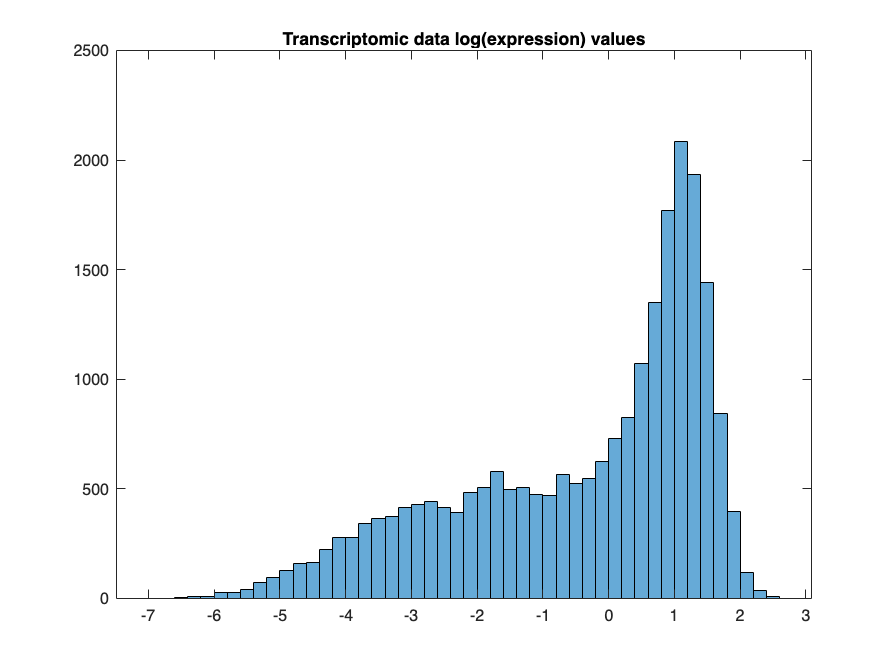

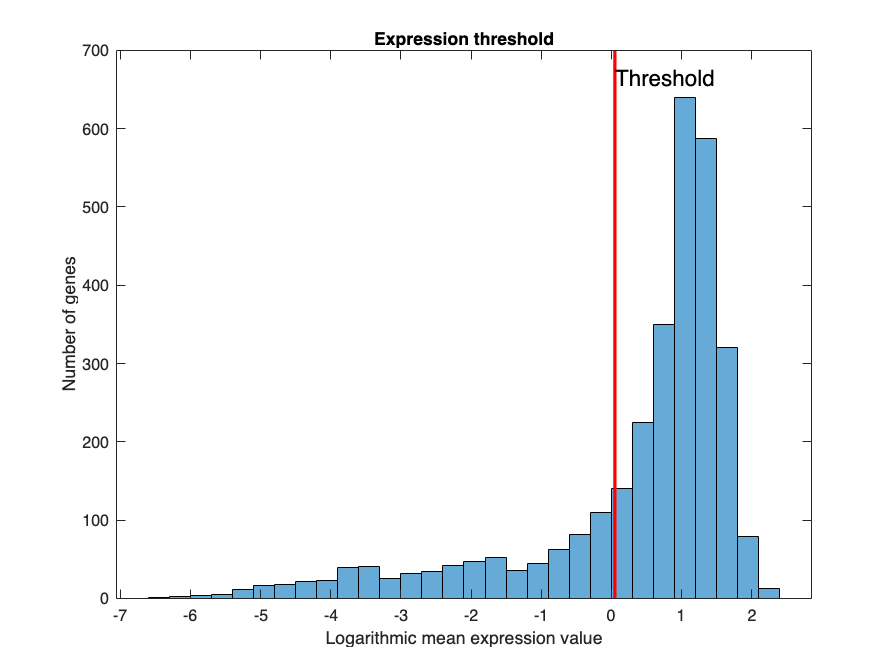

Found biomass reaction: biomass_ob
ATP maintenance reaction is not considered an exchange reaction by default. It should be mass balanced:
ATPM	h2o[c] + atp[c] 	->	h[c] + adp[c] + pi[c] 
252 closed non-core sink/demand reactions via param.nonCoreSinksDemands = closeAll
0 core sink/demand reactions.
0 open core sink/demand reactions.
 
Feasible after closing non-core sink/demand reactions.


rxnsConstrained =

     []


rxnBoundsCorrected =

     []

--------------------------------------------------------------
 
Adding custom constraints ...
 
modelExtractionAlgorithm = fastCore. Ignoring specificData.rxns2constrain for demand reactions, i.e. with prefix DM_
    rxns    lb    ub    constraintDescription    Notes
    ____    __    __    _____________________    _____


The following reactions could not be constrained s

 10052	Flux consistent reactions.
   981	Flux inconsistent reversible reactions left to flip.
 10054	Flux consistent reactions.
   623	Flux inconsistent reversible reactions left to flip.
OPTIMAL


 10057	Flux consistent reactions.
   450	Flux inconsistent reversible reactions left to flip.
 10060	Flux consistent reactions.
   447	Flux inconsistent reversible reactions left to flip.
OPTIMAL


 10063	Flux consistent reactions.
   444	Flux inconsistent reversible reactions left to flip.
OPTIMAL


 10066	Flux consistent reactions.
   441	Flux inconsistent reversible reactions left to flip.
 10069	Flux consistent reactions.
   438	Flux inconsistent reversible reactions left to flip.
5950 flux consistent metabolites
2391 flux inconsistent metabolites
10069 flux consistent reactions
2756 flux inconsistent reactions
--- findFluxConsistentSubset END ----
2391 deleted non-core metabolites,  corresponding to flux inconsistency.
    {'11docrtsl[c]'                            }
    {'11docrtsl[e]'                            }
    {'11docrtsl[m]'                            }
    {'11docrtsl[r]'                            }
    {'11docrtstrn[c]'                          }
    {'11docrtstrn[e]'                          }
    {'11docrtstrn[m]'                          }
    {'11docrtstrn[r]'                          }
    {'12HPET[m]'                               }
    {'12HPET[n]'                               }
    {'12HPET[x]'                               }
    {'12RHPET[c]'            

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


--------------------------------------------------------------
 
Extracting tissue specific model ...
 


 

MSK_RES_OK
LP10: Adaptive scaling factor did not work, switching to fixed scaling factor of 1e4
OPTIMAL


155 deleted non-core metabolites,  corresponding to removal by createTissueSpecificModel.
    {'2hxic_L[c]'         }
    {'2hxic_L[e]'         }
    {'2mpdhl[m]'          }
    {'3hcinnm[c]'         }
    {'3hcinnm[e]'         }
    {'3hppa[c]'           }
    {'3hppa[e]'           }
    {'3octdece1crn[c]'    }
    {'3octdece1crn[e]'    }
    {'C05957[r]'          }
    {'CE2705[n]'          }
    {'CE4876[r]'          }
    {'CE5236[n]'          }
    {'HC00002[c]'         }
    {'HC00002[e]'         }
    {'HC00003[c]'         }
    {'HC00003[e]'         }
    {'HC00004[r]'         }
    {'HC00005[r]'         }
    {'HC00006[r]'         }
    {'HC00007[r]'         }
    {'HC00008[r]'         }
    {'HC00009[r]'         }
    {'HC01852[c]'         }
    {'HC01852[e]'         }
    {'HC01939[c]'         }
    {'HC01939[e]'         }
    {'HC01942[c]'         }
    {'HC01942[e]'         }
    {'HC01943[c]'         }
    {'HC01943[e]'         }
    {'HC01944[c]'         }
    {'HC01944[

Model TCGA-A1-A0SI01_Xomics has been successfully saved


--------------------------------------------------------------
 
XomicsToModel input specificData:
 
             inputData: '/Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/Bibliomic_Gems_actualizado2.xlsx'
           activeGenes: {108×1 cell}
           essentialAA: [9×1 table]
        rxns2constrain: [7×5 table]
       activeReactions: {1459×1 cell}
    presentMetabolites: [39×3 table]
              rxns2add: [2×8 table]
    transcriptomicData: [22599×2 table]
           rxns2remove: []
         inactiveGenes: []

XomicsToModel input param:
 
        inactiveGenesTranscriptomics: 1
                   curationOverOmics: 0
                  metabolomicWeights: 'mean'
             transcriptomicThreshold: 0.05
                    weightsFromOmics: 1
                        fluxCCmethod: 'fastcc'
                          printLevel: 3
                               debug: 0
                       diaryFilename: 0
                  allowRxnRelaxation: 1
   

 
Feasible generic input model.
 
--------------------------------------------------------------
 
Generating model without an objective function.
 
 
--------------------------------------------------------------
Adding 2 reactions ...
 
Metabolite M_cancer_biomass[c] not in model - added to the model


biomass_ob	0.00537 35cgmp[c] + 0.59421 glu_L[c] + 2.4523 asp_L[c] + 0.01963 amp[c] + 0.00805 damp[c] + 0.03272 cmp[c] + 0.02452 pa_hs[c] + 0.42021 ala_L[c] + 0.04268 asn_L[c] + 0.00427 cys_L[c] + 0.67628 gln_L[c] + 0.49244 gly[c] + 0.13132 ser_L[c] + 0.07222 thr_L[c] + 0.03283 lys_L[c] + 0.00328 arg_L[c] + 0.00657 met_L[c] + 0.00646 pail_hs[c] + 0.00347 dag_hs[c] + 0.03755 chsterol[c] + 0.00077 clpn_hs[c] + 0.00537 dcmp[c] + 0.03709 gmp[c] + 0.01963 ump[c] + 0.10177 his_L[c] + 0.0197 tyr_L[c] + 0.01313 ile_L[c] + 0.0394 leu_L[c] + 0.00354 lpchol_hs[c] + 0.00489 mag_hs[c] + 0.00328 trp_L[c] + 0.01313 phe_L[c] + 0.06369 pro_L[c] + 0.01087 ps_hs[c] + 0.00706 sphmyln_hs[c] + 0.04268 val_L[c] + 0.01925 xolest2_hs[c] + 0.00805 dtmp[c] + 0.03407 HC02080[c] + 0.93989 M03161[c] 	->	M_cancer_biomass[c] 
biomass_ex	M_cancer_biomass[c] 	->	
Found biomass reaction: biomass_ob
ATP maintenance reaction is not considered an exchange reaction by default. It should be mass balanced:
ATPM	h2o[c] + atp[c]

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


6.99484e-07 = ||N'*z|| (should be zero)
1171/11646 reactions relaxed.
  8381	 10475	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8381	 10475	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8381	 10475	Confirmed stoichiometrically consistent by leak/siphon testing.
    15	  1171	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 147 metabolites.
arachidonates	12RHPET[c] + prostg1[c] + 12harachd[r] + wharachd[r] + 18harachd[r] + prostge2[r] + 13_cis_retnglc[r] + wharachd[c] + CE0737[c] + CE1243[c] + CE5531[r] + CE4993[c] + CE4993[m] + CE4993[x] + CE2568[c] + CE2568[r] + CE2568[x] + CE2569[c] + CE2569[r] + CE2569[x] + CE5700[c] + CE5726[c] + CE5727[c] + CE5730[c] + C05957[r] + CE4936[c] + CE4936[n] + C05284[c] + C05284[m] + C05284[r] + CE0955[r] + CE3554[c] + CE5141[c] + C06315[r] + C06315[x] + C06314[r] + C06314[x] + CE2305[c] + CE2305[r] + CE2306[c] + CE2306[r] +

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.01581e-07 = ||N'*z|| (should be zero)
575/11645 reactions relaxed.
  8392	 11070	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8392	 11070	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8392	 11070	Confirmed stoichiometrically consistent by leak/siphon testing.
     4	   575	 ... of which are of unknown consistency.
     0	    16	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0012	M01819[e] 	->	0.0001 adrn[e] + 0.0082 arachd[e] + 0.0001 arach[e] + 0.0001 clpnd[e] + 0.0041 crvnc[e] + 0.0001 dcsptn1[e] + 0.002 dlnlcg[e] + 0.0001 eicostet[e] + 0.0001 elaid[e] + 0.3015 hdca[e] + 0.0522 hdcea[e] + 0.0001 hexc[e] + 0.0001 hpdca[e] + 0.0001 lgnc[e] + 0.0001 lneldc[e] + 0.1535 lnlc[e] + 0.0092 lnlnca[e] + 0.0001 lnlncg[e] + 0.0001 nrvnc[e] + 0.046 ocdca[e] + 0.3837 ocdcea[e] + 0.0001 ptdca[e] + 0.0001 strdnc[e] + 0.0001 tethex3[e] + 0.0001 tetpent3[e] + 0.0001 tetpent6[e] + 0.0001 tettet6[e] + 0.00

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.05465e-07 = ||N'*z|| (should be zero)
1205/11629 reactions relaxed.
  8384	 10424	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 10424	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 10424	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	  1205	 ... of which are of unknown consistency.
     0	     6	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0549	0.0007 adrncoa[c] + 0.0005 arachcoa[c] + 0.2125 arachdcoa[c] + 0.1243 pmtcoa[c] + 0.0005 hdcoa[c] + 0.0319 tdcoa[c] + 0.0166 lnlncacoa[c] + 0.0011 lnlncgcoa[c] + 0.0025 strdnccoa[c] + 0.0411 dlnlcgcoa[c] + 0.0221 tmndnccoa[c] + 0.1312 lnlccoa[c] + 0.0067 clpndcoa[c] + 0.0052 dcsptn1coa[c] + 0.0459 c226coa[c] + 0.1983 stcoa[c] + 0.0619 odecoa[c] + 0.0005 lneldccoa[c] + 0.0005 nrvnccoa[c] + 0.0005 ttccoa[c] + 0.0005 hexccoa[c] + 0.0163 eicostetcoa[c] + 0.0005 tetpent6coa[c] + 0.0005 tetpent3coa[c] + 0.0005 tettet6co

OPTIMAL


OPTIMAL


6.11517e-08 = ||N'*z|| (should be zero)
1152/11623 reactions relaxed.
  8383	 10471	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8383	 10471	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8383	 10471	Confirmed stoichiometrically consistent by leak/siphon testing.
    13	  1152	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 55 metabolites.
others	34dhoxmand[c] + 5moxact[c] + 5g2oxpt[x] + 5a2opntn[x] + im4ac[m] + mi3456p[c] + 4aabutn[c] + pepslys[r] + 6pthp[n] + selhcys[c] + dtdprmn[c] + udpxyl[g] + HC02223[m] + CE1943[c] + CE1943[e] + CE1943[x] + CE1936[c] + CE1936[x] + CE2877[c] + CE2877[r] + CE2878[c] + CE2878[r] + CE4788[c] + CE4788[x] + CE2345[m] + tdechola[c] + tdechola[x] + CE5629[c] + CE5274[c] + CE2122[c] + CE5860[c] + CE4881[c] + CE5545[c] + CE5643[c] + CE1562[c] + CE6317[c] + C08261[c] + CE5828[c] + CE5931[c] + CE5924[c] + CE7218[c] + C05708[c] + i

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.60821e-07 = ||N'*z|| (should be zero)
591/11622 reactions relaxed.
  8385	 11031	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11031	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11031	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   591	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0551	0.0031 adrncoa[c] + 0.0005 arachcoa[c] + 0.2118 arachdcoa[c] + 0.0678 pmtcoa[c] + 0.0005 hdcoa[c] + 0.0056 tdcoa[c] + 0.0019 lnlncacoa[c] + 0.0012 lnlncgcoa[c] + 0.0027 strdnccoa[c] + 0.0228 dlnlcgcoa[c] + 0.0043 tmndnccoa[c] + 0.0678 lnlccoa[c] + 0.0101 clpndcoa[c] + 0.0124 dcsptn1coa[c] + 0.0269 c226coa[c] + 0.3553 stcoa[c] + 0.136 odecoa[c] + 0.0005 lneldccoa[c] + 0.0005 nrvnccoa[c] + 0.0005 ttccoa[c] + 0.0005 hexccoa[c] + 0.0179 eicostetcoa[c] + 0.0005 tetpent6coa[c] + 0.0005 tetpent3coa[c] + 0.0005 tettet6coa

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


7.87161e-08 = ||N'*z|| (should be zero)
601/11621 reactions relaxed.
  8385	 11020	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11020	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11020	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   601	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 51 metabolites.
steroids	48dhoxquin[c] + 46dhoxquin[c] + whtststerone[r] + CE2874[r] + CE2183[c] + CE2186[c] + CE2189[c] + C05299[c] + C05299[r] + CE2184[c] + CE5239[c] + CE5239[m] + CE5239[r] + CE5239[x] + CE5242[c] + CE5242[m] + CE5242[r] + CE5242[x] + CE5243[c] + CE5243[m] + CE5243[r] + CE5243[x] + CE5244[c] + CE5244[m] + CE5244[r] + CE5244[x] + CE2176[c] + CE2174[c] + CE5072[c] + CE1293[c] + C05300[c] + C05300[r] + CE5241[c] + CE5241[m] + CE5241[r] + CE5241[x] + CE5240[c] + CE5240[m] + CE5240[r] + CE5240[x] + C05302[c] + CE3086[c] + C

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.07268e-07 = ||N'*z|| (should be zero)
579/11620 reactions relaxed.
  8385	 11041	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11041	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11041	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   579	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 43 metabolites.
xenobiotics	M00944[c] + M01175[c] + M01376[c] + M01242[c] + M00031[c] + M00246[c] + M00244[c] + M00251[c] + M00033[c] + M01302[c] + M01301[c] + M01297[c] + M01299[c] + M01156[c] + M02850[c] + M02144[c] + M01691[c] + M03042[c] + M00724[c] + M00972[c] + M00637[c] + M00571[c] + M00030[c] + M01195[c] + M03038[c] + M00927[c] + M00928[c] + M02607[c] + M00930[c] + M02589[c] + M00917[c] + M02608[c] + M01929[c] + M00542[c] + M00541[c] + M00540[c] + M00544[c] + M00543[c] + M00539[c] + M02853[c] + M00567[c] + 2 M02143[c] + M02855[c] 

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.53557e-05 = ||N'*z|| (should be zero)
631/11618 reactions relaxed.
  8383	 10987	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8383	 10987	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8383	 10987	Confirmed stoichiometrically consistent by leak/siphon testing.
    13	   631	 ... of which are of unknown consistency.
     0	     4	 removed heuristically internal reactions of unknown consistency, each involving 25 metabolites.
r1333	304 h2o[c] + 304 atp[c] + HC00001[c] 	->	304 adp[c] + 304 pi[c] + 62 glu_L[c] + 36 asp_L[c] + 63 ala_L[c] + 17 asn_L[c] + 35 cys_L[c] + 20 gln_L[c] + 13 gly[c] + 28 ser_L[c] + 29 thr_L[c] + 60 lys_L[c] + 27 arg_L[c] + 7 met_L[c] + 16 his_L[c] + 19 tyr_L[c] + 9 ile_L[c] + 64 leu_L[c] + 2 trp_L[c] + 35 phe_L[c] + 24 pro_L[c] + 43 val_L[c] 
r1335	211 h2o[c] + 211 atp[c] + HC00002[c] 	->	211 adp[c] + 211 pi[c] + 29 glu_L[c] + 25 asp_L[c] + 34 ala_L[c] + 19 asn_L[c] + 3 cys_L[c] + 17 gln_L[c] + 16 gly[c] + 30 ser_L[c] + 2

1.70727e-08 = ||N'*z|| (should be zero)
616/11614 reactions relaxed.
  8384	 10998	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 10998	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 10998	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	   616	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 24 metabolites.
HMR_9817	52 h2o[c] + 52 atp[c] + trdrd[c] 	->	52 adp[c] + 52 pi[c] + 10 glu_L[c] + 7 asp_L[c] + 8 ala_L[c] + 3 asn_L[c] + 5 cys_L[c] + 5 gln_L[c] + 5 gly[c] + 7 ser_L[c] + 4 thr_L[c] + 12 lys_L[c] + 3 met_L[c] + his_L[c] + tyr_L[c] + 4 ile_L[c] + 6 leu_L[c] + trp_L[c] + 9 phe_L[c] + 3 pro_L[c] + 11 val_L[c] 
     0	     1	 removed.
Removed reactions:
HMR_9817	HMR_9817
-------
Iteration #10 minimum cardinality of conservation relaxation vector.
    12	   615	 unknown consistency.
  8396	 11613	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.667e-07 = ||N'*z|| (should be zero)
562/11613 reactions relaxed.
  8386	 11051	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8386	 11051	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8386	 11051	Confirmed stoichiometrically consistent by leak/siphon testing.
    10	   562	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0550	0.0043 adrncoa[c] + 0.0005 arachcoa[c] + 0.2005 arachdcoa[c] + 0.0337 pmtcoa[c] + 0.0005 hdcoa[c] + 0.0055 tdcoa[c] + 0.0035 lnlncacoa[c] + 0.0011 lnlncgcoa[c] + 0.0025 strdnccoa[c] + 0.0089 dlnlcgcoa[c] + 0.0286 tmndnccoa[c] + 0.0177 lnlccoa[c] + 0.0329 clpndcoa[c] + 0.0055 dcsptn1coa[c] + 0.0931 c226coa[c] + 0.4731 stcoa[c] + 0.0323 odecoa[c] + 0.0005 lneldccoa[c] + 0.0005 nrvnccoa[c] + 0.0005 ttccoa[c] + 0.0005 hexccoa[c] + 0.0174 eicostetcoa[c] + 0.0005 tetpent6coa[c] + 0.0005 tetpent3coa[c] + 0.0005 tettet6co

OPTIMAL


OPTIMAL


OPTIMAL


5.23384e-08 = ||N'*z|| (should be zero)
583/11612 reactions relaxed.
  8385	 11029	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11029	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11029	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   583	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 43 metabolites.
HMR_5167	420 h2o[c] + 315 atp[c] + M02421[c] + 8 M02335[c] + 3 M02341[c] + 7 M02342[c] + 5 M02351[c] + 5 M02376[c] + 10 M02377[c] + 5 M02006[c] + M02380[c] + 4 M02401[c] + 6 M02404[c] + 12 M02405[c] + 3 M02408[c] + 9 M02412[c] + 3 M02415[c] + 7 M02416[c] + 4 M02419[c] + M02420[c] + 11 M02423[c] 	->	315 adp[c] + 315 pi[c] + trdrd[c] + M03081[c] + 8 M03063[c] + 3 M03065[c] + 7 M03066[c] + 5 M03067[c] + 5 M03068[c] + 10 M03069[c] + 5 M03070[c] + M03071[c] + 4 M03072[c] + 6 M03073[c] + 12 M03074[c] + 3 M03075[c] + 9 M03076[c] 

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.95367e-07 = ||N'*z|| (should be zero)
560/11611 reactions relaxed.
  8384	 11051	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 11051	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 11051	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	   560	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 60 metabolites.
HMR_0560	0.557 HC02029[c] + 0.002 HC02030[c] + 0.138 HC02031[c] + 0.061 HC02032[c] + 0.025 HC02033[c] + 0.0136 HC02036[c] + 0.002 M00484[c] + 0.002 M00502[c] + 0.011 M00493[c] + 0.002 M00471[c] + 0.002 M00463[c] + 0.002 M00454[c] + 0.002 M00498[c] + 0.0358 M00461[c] + 0.002 M00481[c] + 0.002 M00438[c] + 0.002 M00469[c] + 0.002 M00448[c] + 0.0453 M00474[c] + 0.002 M00470[c] + 0.002 M00462[c] + 0.002 M00458[c] + 0.002 M00494[c] + 0.002 M00478[c] + 0.002 M00447[c] + 0.002 M00442[c] + 0.002 M00468[c] + 0.002 M00465[c] + 0.002 

OPTIMAL


OPTIMAL


OPTIMAL


3.63552e-08 = ||N'*z|| (should be zero)
552/11610 reactions relaxed.
  8386	 11058	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8386	 11058	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8386	 11058	Confirmed stoichiometrically consistent by leak/siphon testing.
    10	   552	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 26 metabolites.
r1293	420 h2o[c] + 420 atp[c] + 10 glu_L[c] + 7 asp_L[c] + 8 ala_L[c] + 3 asn_L[c] + 5 cys_L[c] + 5 gln_L[c] + 5 gly[c] + 7 ser_L[c] + 4 thr_L[c] + 12 lys_L[c] + 3 met_L[c] + his_L[c] + tyr_L[c] + 4 ile_L[c] + 6 leu_L[c] + trp_L[c] + 9 phe_L[c] + 3 pro_L[c] + 11 val_L[c] 	->	315 adp[c] + 315 pi[c] + 105 amp[c] + 105 ppi[c] + trdrd[c] 
     0	     1	 removed.
Removed reactions:
r1293	Adf Protein Assembly
-------
Iteration #14 minimum cardinality of conservation relaxation vector.
    10	   551	 unknown consistency.
  8396	 

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


3.96995e-08 = ||N'*z|| (should be zero)
577/11609 reactions relaxed.
  8385	 11032	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11032	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11032	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   577	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 23 metabolites.
r1339	133 h2o[c] + 133 atp[c] + HC00004[c] 	->	133 adp[c] + 133 pi[c] + 30 glu_L[c] + 16 asp_L[c] + 23 ala_L[c] + 5 asn_L[c] + 19 gln_L[c] + 11 gly[c] + 16 ser_L[c] + 12 thr_L[c] + 22 lys_L[c] + 17 arg_L[c] + 4 met_L[c] + 6 his_L[c] + 7 tyr_L[c] + 41 leu_L[c] + 5 trp_L[c] + 8 phe_L[c] + 10 pro_L[c] + 15 val_L[c] 
r1344	50 h2o[c] + 50 atp[c] + HC00007[c] 	->	50 adp[c] + 50 pi[c] + 8 glu_L[c] + 4 asp_L[c] + 7 ala_L[c] + asn_L[c] + 8 gln_L[c] + 5 gly[c] + 9 ser_L[c] + 10 thr_L[c] + 6 lys_L[c] + 2 arg_L[c] + 3 met_L[c] + 5 tyr

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


8.48905e-08 = ||N'*z|| (should be zero)
574/11607 reactions relaxed.
  8385	 11033	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11033	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11033	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   574	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 22 metabolites.
r1343	41 h2o[c] + 41 atp[c] + HC00006[c] 	->	41 adp[c] + 41 pi[c] + 8 glu_L[c] + 4 asp_L[c] + 5 ala_L[c] + asn_L[c] + 3 gln_L[c] + 3 gly[c] + 9 ser_L[c] + 3 thr_L[c] + 9 lys_L[c] + 4 arg_L[c] + 2 met_L[c] + 4 ile_L[c] + 12 leu_L[c] + trp_L[c] + 4 phe_L[c] + 4 pro_L[c] + 7 val_L[c] 
r1345	49 h2o[c] + 49 atp[c] + HC00008[c] 	->	49 adp[c] + 49 pi[c] + 5 glu_L[c] + 7 asp_L[c] + 15 ala_L[c] + 6 gln_L[c] + 3 gly[c] + 12 ser_L[c] + 5 thr_L[c] + 6 lys_L[c] + 4 arg_L[c] + 3 met_L[c] + his_L[c] + 2 tyr_L[c] + 11 leu_L[c] + 3 trp_L[c

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.03985e-07 = ||N'*z|| (should be zero)
567/11605 reactions relaxed.
  8385	 11038	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11038	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11038	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   567	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 13 metabolites.
HDL_HSDEG	h2o[e] + hdl_hs[e] 	->	2 chsterol[e] + 2 pchol_hs[e] + Rtotal[e] + Rtotal2[e] + Rtotal3[e] + glyc[e] + HC00004[e] + HC00006[e] + HC00007[e] + HC00008[e] + HC00009[e] 
HMR_1065	2 h2o[c] + o2[c] + 2 h[c] + atp[c] + nad[c] + coa[c] + C14770[c] 	->	h2o2[c] + nadh[c] + accoa[c] + amp[c] + ppi[c] + CE2725[c] 
     0	     2	 removed.
Removed reactions:
HDL_HSDEG	Degradation of HDL
HMR_1065	3-Hydroxyacyl Coenzyme A Dehydrogenase
-------
Iteration #17 minimum cardinality of conservation relaxation vector.
    11	   565	 u

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


3.61083e-06 = ||N'*z|| (should be zero)
586/11603 reactions relaxed.
  8383	 11017	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8383	 11017	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8383	 11017	Confirmed stoichiometrically consistent by leak/siphon testing.
    13	   586	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 12 metabolites.
HMR_1068	2 h2o[c] + o2[c] + atp[c] + nad[c] + coa[c] + C14771[c] 	->	h2o2[c] + nadh[c] + accoa[c] + amp[c] + ppi[c] + M00310[c] 
     0	     1	 removed.
Removed reactions:
HMR_1068	3-Hydroxyacyl Coenzyme A Dehydrogenase
-------
Iteration #18 minimum cardinality of conservation relaxation vector.
    13	   585	 unknown consistency.
  8396	 11602	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


4.79752e-08 = ||N'*z|| (should be zero)
572/11602 reactions relaxed.
  8386	 11030	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8386	 11030	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8386	 11030	Confirmed stoichiometrically consistent by leak/siphon testing.
    10	   572	 ... of which are of unknown consistency.
     0	    19	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAEL183	o2[c] + 5 h[c] + 4 nadph[c] + lnlncgcoa[c] + malcoa[c] 	->	3 h2o[c] + 4 nadp[c] + co2[c] + coa[c] + dlnlcgcoa[c] 
FAEL184	o2[c] + 5 h[c] + 4 nadph[c] + strdnccoa[c] + malcoa[c] 	->	3 h2o[c] + 4 nadp[c] + co2[c] + coa[c] + eicostetcoa[c] 
FAEL204	o2[c] + 5 h[c] + 4 nadph[c] + arachdcoa[c] + malcoa[c] 	->	3 h2o[c] + 4 nadp[c] + co2[c] + coa[c] + adrncoa[c] 
FAEL205	o2[c] + 5 h[c] + 4 nadph[c] + tmndnccoa[c] + malcoa[c] 	->	3 h2o[c] + 4 nadp[c] + co2[c] + coa[c] + clpndcoa[c] 
FAOXC16080x	4 nad[x] + 4 coa[x] + pmtcoa[

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


3.7535e-08 = ||N'*z|| (should be zero)
498/11583 reactions relaxed.
  8385	 11085	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11085	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11085	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   498	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC11BRC9BRx	h[x] + nad[x] + coa[x] + o2[x] + h2o[x] + tmuncoa[x] 	->	nadh[x] + h2o2[x] + dmnoncoa[x] + ppcoa[x] 
3HPVSTETCOAhcx	2 nad[x] + 2 coa[x] + o2[x] + 2 h2o[x] + 3hpvscoa[x] 	->	2 h[x] + 2 nadh[x] + 2 accoa[x] + 2 h2o2[x] + 3hpvstetcoa[x] 
     0	     2	 removed.
Removed reactions:
FAOXC11BRC9BRx	Fatty Acid Beta Oxidation (C11Br->C9Br), Peroxisomal
3HPVSTETCOAhcx	beta oxidation of 3-S-hydroxy-pravastatin-CoA to tetranor-CoA in hepatocytes, peroxisomes
-------
Iteration #20 minimum cardinality of conservation rela

7.14e-08 = ||N'*z|| (should be zero)
489/11581 reactions relaxed.
  8385	 11092	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11092	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11092	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   489	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC12DCC10DCx	nad[x] + coa[x] + o2[x] + h2o[x] + c12dccoa[x] 	->	h[x] + nadh[x] + accoa[x] + h2o2[x] + sebcoa[x] 
     0	     1	 removed.
Removed reactions:
FAOXC12DCC10DCx	Fatty Acid Beta Oxidation (C12Dc->C10Dc), Peroxisomal
-------
Iteration #21 minimum cardinality of conservation relaxation vector.
    11	   488	 unknown consistency.
  8396	 11580	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


5.22357e-08 = ||N'*z|| (should be zero)
457/11580 reactions relaxed.
  8393	 11123	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8393	 11123	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8393	 11123	Confirmed stoichiometrically consistent by leak/siphon testing.
     3	   457	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 12 metabolites.
CHYLO_HSDEG	h2o[e] + chylo_hs[e] 	->	Rtotal[e] + Rtotal2[e] + Rtotal3[e] + glyc[e] + HC00004[e] + HC00005[e] + HC00006[e] + HC00007[e] + HC00008[e] + HC00009[e] 
     0	     1	 removed.
Removed reactions:
CHYLO_HSDEG	Degradation of Chylomicron
-------
Iteration #22 minimum cardinality of conservation relaxation vector.
     3	   456	 unknown consistency.
  8396	 11579	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.16552e-07 = ||N'*z|| (should be zero)
340/11579 reactions relaxed.
  8393	 11239	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8393	 11239	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8393	 11239	Confirmed stoichiometrically consistent by leak/siphon testing.
     3	   340	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC6DCC4DCx	nad[x] + coa[x] + o2[x] + h2o[x] + adpcoa[x] 	->	h[x] + nadh[x] + accoa[x] + h2o2[x] + succoa[x] 
     0	     1	 removed.
Removed reactions:
FAOXC6DCC4DCx	Fatty Acid Beta Oxidation (C6Dc->C4Dc), Peroxisomal
-------
Iteration #23 minimum cardinality of conservation relaxation vector.
     3	   339	 unknown consistency.
  8396	 11578	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


5.84707e-08 = ||N'*z|| (should be zero)
513/11578 reactions relaxed.
  8385	 11065	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11065	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11065	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   513	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC16C14x	nad[x] + coa[x] + pmtcoa[x] + o2[x] + h2o[x] 	->	h[x] + nadh[x] + accoa[x] + tdcoa[x] + h2o2[x] 
     0	     1	 removed.
Removed reactions:
FAOXC16C14x	Fatty Acid Beta Oxidation (C16->C14), Peroxisomal
-------
Iteration #24 minimum cardinality of conservation relaxation vector.
    11	   512	 unknown consistency.
  8396	 11577	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


3.23527e-08 = ||N'*z|| (should be zero)
482/11577 reactions relaxed.
  8385	 11095	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11095	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11095	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   482	 ... of which are of unknown consistency.
     0	    23	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.
ARTFR13	tdcoa[c] 	->	0.875 R1coa_hs[c] 
ARTFR204	2 h[m] + 2 nadph[m] + 2 fadh2[m] + strdnccoa[c] 	->	2 nadp[m] + 2 fad[m] + 1.125 R2coa_hs[c] 
ARTFR209	2 h[m] + 2 nadph[m] + 2 fadh2[m] + adrncoa[c] 	->	2 nadp[m] + 2 fad[m] + 1.375 R2coa_hs[c] 
ARTFR211	2 h[m] + 2 nadph[m] + 3 fadh2[m] + clpndcoa[c] 	->	2 nadp[m] + 3 fad[m] + 1.375 R2coa_hs[c] 
ARTFR212	2 h[m] + 2 nadph[m] + 3 fadh2[m] + dcsptn1coa[c] 	->	2 nadp[m] + 3 fad[m] + 1.375 R2coa_hs[c] 
ARTFR213	3 h[m] + 3 nadph[m] + 3 fadh2[m] + c226c

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.65571e-08 = ||N'*z|| (should be zero)
445/11554 reactions relaxed.
  8393	 11109	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8393	 11109	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8393	 11109	Confirmed stoichiometrically consistent by leak/siphon testing.
     3	   445	 ... of which are of unknown consistency.
     0	     5	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.
ARTFR205	h[m] + nadph[m] + 2 fadh2[m] + dlnlcgcoa[c] 	->	nadp[m] + 2 fad[m] + 1.25 R2coa_hs[c] 
ARTFR206	2 h[m] + 2 nadph[m] + 2 fadh2[m] + arachdcoa[c] 	->	2 nadp[m] + 2 fad[m] + 1.25 R2coa_hs[c] 
ARTFR207	arachcoa[c] 	->	1.25 R2coa_hs[c] 
ARTFR208	2 h[m] + 2 nadph[m] + 3 fadh2[m] + tmndnccoa[c] 	->	2 nadp[m] + 3 fad[m] + 1.25 R2coa_hs[c] 
ARTFR210	h[m] + nadph[m] + fadh2[m] + lnlccoa[c] 	->	nadp[m] + fad[m] + 1.125 R2coa_hs[c] 
     0	     5	 removed.
Removed reactions:
ARTFR205	R Group Artif

OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


8.71038e-08 = ||N'*z|| (should be zero)
454/11549 reactions relaxed.
  8385	 11095	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8385	 11095	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8385	 11095	Confirmed stoichiometrically consistent by leak/siphon testing.
    11	   454	 ... of which are of unknown consistency.
     0	     2	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.
ARTFR202	h[m] + nadph[m] + 2 fadh2[m] + lnlncacoa[c] 	->	nadp[m] + 2 fad[m] + 1.125 R2coa_hs[c] 
ARTFR203	h[m] + nadph[m] + 2 fadh2[m] + lnlncgcoa[c] 	->	nadp[m] + 2 fad[m] + 1.125 R2coa_hs[c] 
     0	     2	 removed.
Removed reactions:
ARTFR202	R Group Artificial Flux (C18:3, N-3)
ARTFR203	R Group Artificial Flux
-------
Iteration #27 minimum cardinality of conservation relaxation vector.
    11	   452	 unknown consistency.
  8396	 11547	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


8.82183e-08 = ||N'*z|| (should be zero)
473/11547 reactions relaxed.
  8377	 11074	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8377	 11074	 subset tested for leakage (dc method, with infinite flux bounds)...
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.
OPTIMAL


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8377	 11074	Confirmed stoichiometrically consistent by leak/siphon testing.
    19	   473	 ... of which are of unknown consistency.
     0	     1	 removed heuristically internal reactions of unknown consistency, each involving 10 metabolites.
FAOXC180x	nad[x] + coa[x] + o2[x] + h2o[x] + stcoa[x] 	->	h[x] + nadh[x] + accoa[x] + pmtcoa[x] + h2o2[x] 
     0	     1	 removed.
Removed reactions:
FAOXC180x	Beta Oxidation of Long Chain Fatty Acid
-------
Iteration #28 minimum cardinality of conservation relaxation vector.
    19	   472	 unknown consistency.
  8396	 11546	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.31104e-07 = ||N'*z|| (should be zero)
469/11546 reactions relaxed.
  8384	 11077	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 11077	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 11077	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	   469	 ... of which are of unknown consistency.
     0	     0	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.
-------
Iteration #29 minimum cardinality of conservation relaxation vector.
    12	   469	 unknown consistency.
  8396	 11546	 being tested.
OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


OPTIMAL


1.31104e-07 = ||N'*z|| (should be zero)
469/11546 reactions relaxed.
  8384	 11077	 ... of which are stoichiometrically consistent by min cardinality of stoich consistency relaxation.
  8384	 11077	 subset tested for leakage (dc method, with infinite flux bounds)...


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
     0	     0	 semipositive leaking metabolites (and exclusive reactions).
     0	     0	 seminegative siphon metabolites (and exclusive reactions).
  8384	 11077	Confirmed stoichiometrically consistent by leak/siphon testing.
    12	   469	 ... of which are of unknown consistency.
     0	     0	 removed heuristically internal reactions of unknown consistency, each involving 9 metabolites with non-integer coefficients.


 

MSK_RES_OK
Infeasibility while detecting semipositive leaking metabolites.


 

MSK_RES_OK
Infeasibility while detecting seminegative leaking metabolites.
--- Summary of stoichiometric consistency ----
  8400	 13545	 totals.
     4	  1899	 heuristically external.
  8396	 11646	 heuristically internal:
  8384	 11077	 ... of which are stoichiometrically consistent.
     0	   100	 ... of which are stoichiometrically inconsistent.
    12	   469	 ... of which are of unknown consistency.
  8384	 11077	 Confirmed stoichiometrically consistent by leak/siphon testing.
--- findStoichConsistentSubset END ----
3 deleted non-core metabolites,  corresponding to stoichiometric inconsistency.
    {'Temp001[c]'     }
    {'glgchlo[c]'     }
    {'neuromelanin[c]'}

1 deleted core metabolites,  corresponding to stoichiometric inconsistency.
             mets                     metNames        
    _______________________    _______________________

    {'M_cancer_biomass[c]'}    {'M_cancer_biomass[c]'}

81 dele

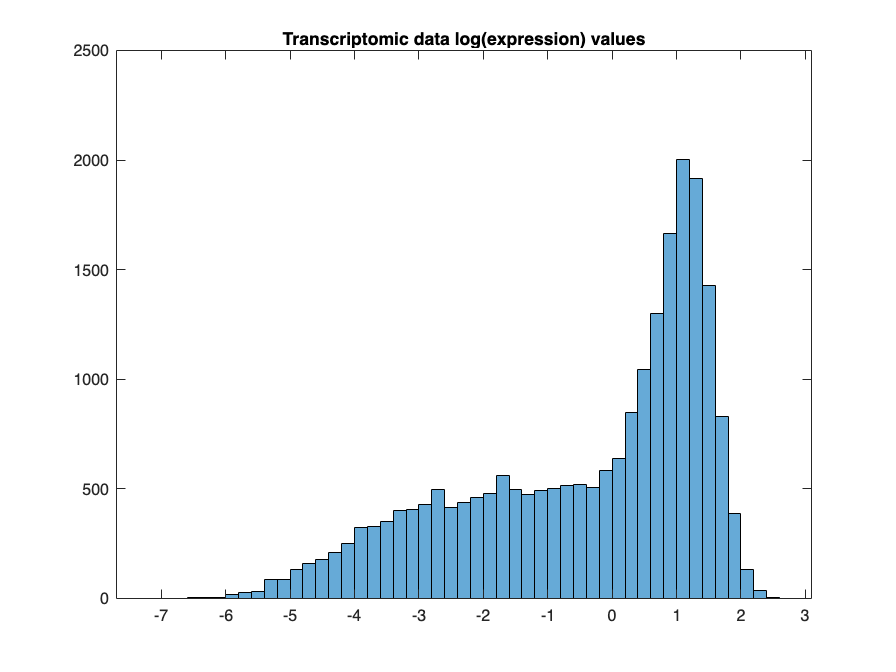

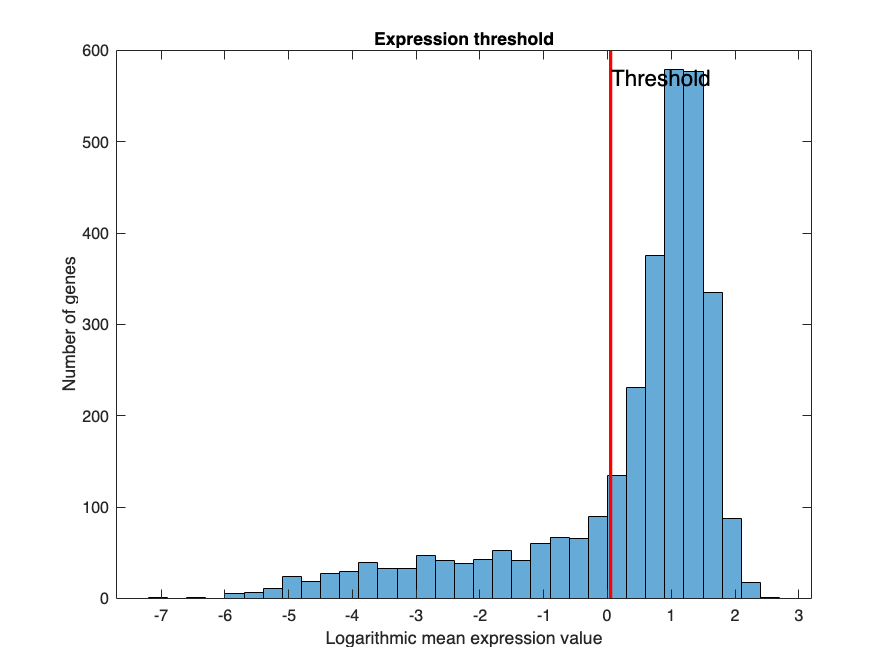

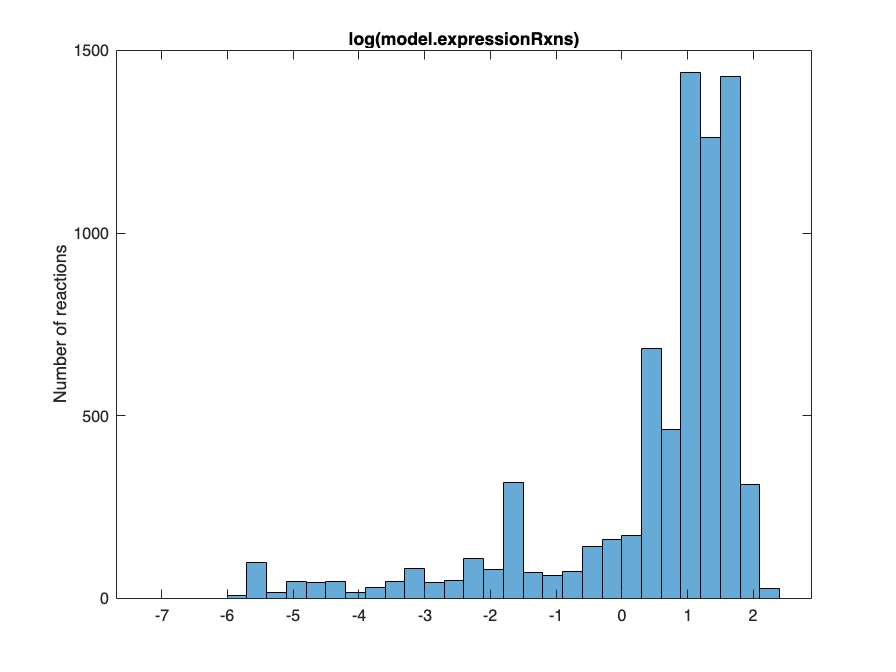

Found biomass reaction: biomass_ob
ATP maintenance reaction is not considered an exchange reaction by default. It should be mass balanced:
ATPM	h2o[c] + atp[c] 	->	h[c] + adp[c] + pi[c] 
252 closed non-core sink/demand reactions via param.nonCoreSinksDemands = closeAll
0 core sink/demand reactions.
0 open core sink/demand reactions.
 
Feasible after closing non-core sink/demand reactions.


rxnsConstrained =

     []


rxnBoundsCorrected =

     []

--------------------------------------------------------------
 
Adding custom constraints ...
 
modelExtractionAlgorithm = fastCore. Ignoring specificData.rxns2constrain for demand reactions, i.e. with prefix DM_
    rxns    lb    ub    constraintDescription    Notes
    ____    __    __    _____________________    _____


The following reactions could not be constrained s

 

MSK_RES_OK
284 genes were specified as inactive but not removed as they are involved in reactions that may be catalysed by other gene products, or are essential.
 
Deleted metabolites:
    {'5moxact[c]' }
    {'Nacsertn[c]'}
    {'12RHPET[c]' }
    {'pro_D[x]'   }
    {'1p2cbxl[x]' }
    {'alpam[m]'   }
    {'lpro[m]'    }
    {'alpro[m]'   }
    {'dhlpro[m]'  }
    {'5forthf[c]' }
    {'mmcoa_S[c]' }
    {'mmcoa_S[x]' }
    {'nmthsrtn[c]'}
    {'34dhcinm[c]'}
    {'CE1935[x]'  }
    {'CE1940[x]'  }
    {'CE1943[x]'  }
    {'CE1936[x]'  }
    {'CE1939[x]'  }
    {'CE2915[c]'  }
    {'CE4722[c]'  }
    {'CE2916[c]'  }
    {'CE4723[c]'  }
    {'CE2917[c]'  }
    {'CE4724[c]'  }
    {'CE2203[m]'  }
    {'CE5654[r]'  }
    {'CE1554[m]'  }
    {'CE1556[m]'  }
    {'CE2020[m]'  }
    {'CE2211[r]'  }
    {'CE5072[r]'  }
    {'CE5082[m]'  }
    {'C03958[c]'  }
    {'CE5820[c]'  }
    {'CE6027[m]'  }
    {'C06199[g]'  }
    {'CE6316[g]'  }
    {'C06199[l]'  }
    {'CE6316[l]'  }
    {'CE5663

 

MSK_RES_OK


 

MSK_RES_OK
Infeasible model after removing inactive genes (that do not affect core reactions), relaxing ...

          steadyStateRelax: 0
                printLevel: 3
         relaxedPrintLevel: 1
             internalRelax: 0
             exchangeRelax: 2
                     maxUB: 10000
                     minLB: -10000
                 maxRelaxR: 1000000
    toBeUnblockedReactions: [12538×1 double]
        excludedReactionLB: [12538×1 logical]
        excludedReactionUB: [12538×1 logical]
       excludedMetabolites: [8342×1 logical]
            nbMaxIteration: 20
                   epsilon: 1e-06
                     theta: 0.1
                     alpha: 1
                    lambda: 1
                     gamma: 0
                    alpha0: 1
                   lambda0: 1
                    gamma0: 0
                    alpha1: 1e-06
                   lambda1: 1e-06
                    gamma1: 1e-06



 

MSK_RES_OK
          steadyStateRelax: 0
                printLevel: 3
         relaxedPrintLevel: 1
             internalRelax: 0
             exchangeRelax: 2
                     maxUB: 10000
                     minLB: -10000
                 maxRelaxR: 1000000
    toBeUnblockedReactions: [12538×1 double]
        excludedReactionLB: [12538×1 logical]
        excludedReactionUB: [12538×1 logical]
       excludedMetabolites: [8342×1 logical]
            nbMaxIteration: 20
                   epsilon: 1e-06
                     theta: 0.1
                     alpha: 1
                    lambda: 1
                     gamma: 0
                    alpha0: 1
                   lambda0: 1
                    gamma0: 0
                    alpha1: 1e-06
                   lambda1: 1e-06
                    gamma1: 1e-06
         excludedReactions: [12538×1 logical]



 

MSK_RES_OK
          steadyStateRelax: 0
                printLevel: 3
         relaxedPrintLevel: 1
             internalRelax: 0
             exchangeRelax: 2
                     maxUB: 10000
                     minLB: -10000
                 maxRelaxR: 1000000
    toBeUnblockedReactions: [12538×1 double]
        excludedReactionLB: [12538×1 logical]
        excludedReactionUB: [12538×1 logical]
       excludedMetabolites: [8342×1 logical]
            nbMaxIteration: 20
                   epsilon: 1e-06
                     theta: 0.1
                     alpha: 1
                    lambda: 1
                     gamma: 0
                    alpha0: 1
                   lambda0: 1
                    gamma0: 0
                    alpha1: 1e-06
                   lambda1: 1e-06
                    gamma1: 1e-06
         excludedReactions: [12538×1 logical]



Error using  - 
Arrays have incompatible sizes for this operation.

Error in relaxFBA_cappedL1>relaxFBA_cappedL1_solveSubProblem (line 325)
    obj = [c-v_bar; -r_bar; (theta*ones(n,1).*alpha0 -p_bar); (theta*ones(n,1).*alpha0 -q_bar); (ones(n,1).*gamma0); (ones(m,1).*lambda0)];

Error in 


% Define output directory
outputDir = '/Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/GEMs cancer';

% Verify output directory exists
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

%% Transcriptomic Integration

% Clean gene IDs
genes = cell(numel(model.genes), 1);
pattern = '\\d+';  % Pattern to extract numeric part of the gene IDs
for i = 1:numel(model.genes)
    match = regexp(model.genes{i}, pattern, 'match', 'once');
    genes{i} = match;
end
model.genes = genes;

% Clean grRules
grRules = cell(numel(model.grRules), 1);
pattern = '[_,.#/-]\\w*';
for i = 1:numel(model.grRules)
    newElem = regexprep(model.grRules{i}, pattern, '');
    grRules{i} = newElem;
end
model.grRules = grRules;

model.biomassRxnAbbr = 'biomass_ob';

% General parameters
param.inactiveGenesTranscriptomics = true; 
param.curationOverOmics = false;

param.metabolomicWeights = 'mean';
param.transcriptomicThreshold = 0.05; 
param.weightsFromOmics = true;
param.fluxCCmethod = 'fastcc'; 
param.printLevel = 3;          
param.debug = false;            
param.diaryFilename = 0;
param.verbose = false;

getCobraSolverParams('LP', 'feasTol', 1e-6);  
feasTol = getCobraSolverParams('LP', 'feasTol');

param.allowRxnRelaxation = true;
param.TolMinBoundary = -1e4;
param.TolMaxBoundary = 1e4;
param.boundPrecisionLimit = feasTol * 100;   
param.fluxEpsilon = feasTol * 100;           

param.closeIons = false; 
param.closeUptakes = false;
param.nonCoreSinksDemands = 'closeAll';
param.sinkDMinactive = false;     
param.allowNetFlux = true;
param.protectEssentialRxns = true;
param.protectRxns = {'biomass_ob','biomass_ex'};
param.activeGenesApproach = 'oneRxnPerActiveGene';
param.modelExtractionAlgorithm = 'thermoKernel';
param.coreFromActiveGenes = true;
param.core = {'biomass_ob','biomass_ex'};
params.specificRxns = {'biomass_ob', 'biomass_ex'};

% Generate specific GEMs

for i = 1:length(XomicsFilesNames)  
    specificData.transcriptomicData = readtable(XomicsFilesNames{i});
    [specificModel, ~] = XomicsToModel(model, specificData, param);
    specificModelPath = fullfile('/Users/eduardoruiz/Documents/MCBCI/MCBCI2/Sistemas metabólicos/Modelos cancer/GEMs cancer/ModelsFinals', ...
                             [filesNames{i}, '_specificModel.mat']);
    delete(fullfile(pwd, '*thermoKernel*'));
    save(specificModelPath, "specificModel");
    disp(['Model ', filesNames{i}, ' has been successfully saved']);
end


disp("Models have been made successfully");
